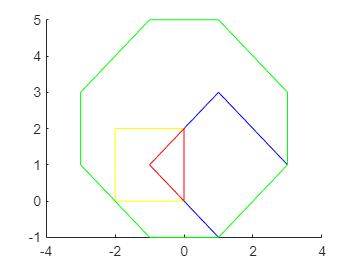

% construct zonotope
Z1 = zonotope([1 1 1; 1 -1 1]);
Z2 = zonotope([-1 1 0; 1 0 1]);

% convert zonotope Z2 to halfspace representation
P1 = mptPolytope(Z1);
P2 = mptPolytope(Z2);
P3 = P1 + P2;
P4 = P1 & P2;

% visualization
figure; hold on;
plot(P1,[1,2],'-b');
plot(P2,[1,2],'y');
plot(P3,[1,2],'g');
plot(P4,[1,2],'r');


A = P1.P.A;
b = P1.P.b;
v = P1.P.V;
n = size(A,2);
syms B d lambda_u lambda_v
%Lagrangian method
f = log(det(inv(B)));


%initialize
x0 = rand(n,n+2);
fun(x0,A,b,v);

Unrecognized function or variable 'fun'.

[x,fval,exitflag,output,lambda,grad,hessian] = fmincon(@fun,x0);

Z1 = zonotope([4 1 1; -2.4 -1 1.5]);
P1 = mptPolytope(Z1);
% Z2 = zonotope([-1 1 0; 1 0 1]);
% P2 = mptPolytope(Z2);
% P3 = P1 & P2;

A = P1.P.A;
b = P1.P.b;
m = size(A,1);
n = size(A,2);
cvx_begin
    variable B(n,n) symmetric
    variable d(n)
    maximize( det_rootn( B ) )
    subject to
       for i = 1:m
           norm( B*A(i,:)', 2 ) + A(i,:)*d <= b(i);
       end
cvx_end

 
Calling SDPT3 4.0: 30 variables, 14 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 14
 dim. of sdp    var  =  6,   num. of sdp  blk  =  2
 dim. of socp   var  = 12,   num. of socp blk  =  4
 dim. of linear var  =  5
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.8e+01|4.3e+00|1.2e+03| 2.185514e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.777|8.0e-06|1.0e+00|2.9e+02| 5.302905e+01 -7.152207e+00| 0:0:00| chol  1  1 
 2|1.000|0.995|3.3e-06|9.7e-03|3.2e+01| 3.073699e+01  2.680451e-02| 0:0:0

[U,S,V] = svd(B);
Q = U * (S.*S)* U';
c = [1 0;0 1];
[U_,S_,V_] = svd(c);
Q_ = U_ * (S_.*S_)* U_';
E_ = ellipsoid(Q_,d);
plot(E_);
ZE = zonotope(E_,8,'inner:norm');
plot(ZE);
tic
EE = B * ZE; 
new_g = EE.Z(:,2:end);
EE_new = zonotope(d,new_g);
toc

Elapsed time is 3.066958 seconds.


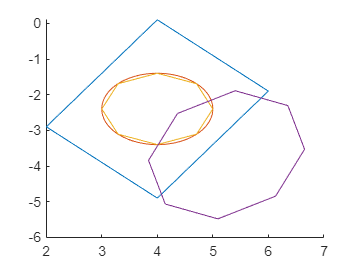

plot(EE);
hold on;

% B_ = normalize(B,'norm');
clf;
%representing ellipsoid with CORA
E = ellipsoid(Q,d);
% E_ = ellipsoid(B_,d);
tic
ZE = zonotope(E,8,'inner:norm');
toc

Elapsed time is 4.786558 seconds.


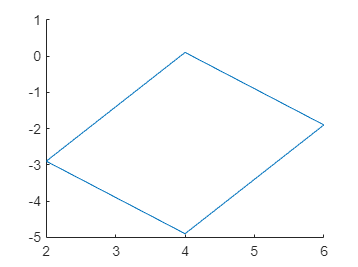

% ZE_ = zonotope(E_,8,'inner:norm');
% plot(E);
hold on;
% plot(ZE);
% plot(zonotope(E,8,'inner:norm')); 
% make the plots
noangles = 200;
angles   = linspace( 0, 2 * pi, noangles );
ellipse_inner  = B * [ cos(angles) ; sin(angles) ] + d * ones( 1, noangles );

%try to creat zonotope from ellipsoid
nog = 8; %number of generators
angles = linspace( -pi/2, pi/2, nog);
ori_gen =  [cos(angles) ; sin(angles)]; % base generator from circle
tran_gen = normalize(B,'norm') * ori_gen/4; % transformed generator for ellipsoid
ZZ_E = zonotope(d,tran_gen);



hold on;
% plot( ellipse_inner(1,:), ellipse_inner(2,:), 'r--' );
hold on;
plot(P1);

% plot(ZE);
% plot(ZZ_E);
% plot(tran_gen(1,:),tran_gen(2,:),'b--');

clf
e = ellipsoid([1 0;0 1],[0;0]);
plot(e);
hold on;
plot(zonotope(e,8,'inner:norm')); 

norm_B = normalize(B,'norm');
ratio = B/norm_B

ratio =     1.4142         0
   -0.0000    1.8028


syms x;
fmin = @(x) norm((B * [cos(x);sin(x)]),2);
fmax = @(x) -norm((B * [cos(x);sin(x)]),2);
lb = 0;
ub = 2 * pi;
A = [];
b = [];
Aeq = [];
beq = [];
x0 = pi;
[alpha_min,short_axis] = fmincon(fmin,x0,A,b,Aeq,beq,lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[alpha_max,long_axis] = fmincon(fmax,x0,A,b,Aeq,beq,lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Q = [cos(alpha_min) cos(alpha_max);sin(alpha_min) sin(alpha_max)]*diag([short_axis^2 long_axis^2])*[cos(alpha_min) cos(alpha_max);sin(alpha_min) sin(alpha_max)]'

Q =     1.9999    0.5000
    0.5000    3.2501


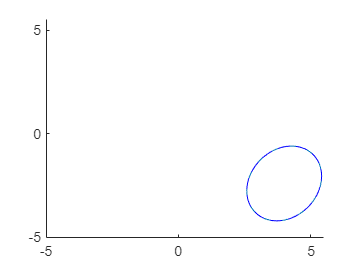

Q_ = U * (S.*S)* U';
E = ellipsoid(Q,d);
E_ = ellipsoid(Q_,d);
noangles = 200;
angles   = linspace( 0, 2 * pi, noangles );
ellipse_inner  = B * [ cos(angles) ; sin(angles) ] + d * ones( 1, noangles );
figure();
hold on;
xlim([-5 5.5]);ylim([-5 5.5]);
% plot(E);
plot(E_);
% figure();
% xlim([2.5 5.5]);ylim([-5 -1]);
% plot(E_);
% figure();
% xlim([2.5 5.5]);ylim([-5 -1]);
plot(ellipse_inner(1,:), ellipse_inner(2,:),'b--');

%try to create higher dimensional generator for zonotope
